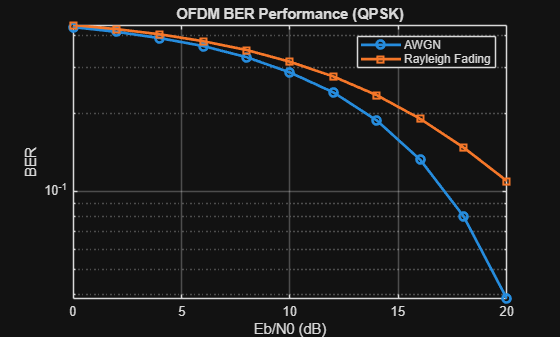

clc; clear; close all;

%% Parameters
N = 64;                 % Number of subcarriers
cp_len = 16;            % Cyclic prefix length
numSymbols = 1e4;       % Number of OFDM symbols
EbN0_dB = 0:2:20;       

M = 4;                  % QPSK
k = log2(M);

ber_awgn = zeros(size(EbN0_dB));
ber_rayleigh = zeros(size(EbN0_dB));

%% Generate Data
bits = randi([0 1], numSymbols*N*k, 1);

% QPSK Modulation
symbols = qammod(bits, M, 'InputType', 'bit', 'UnitAveragePower', true);

% Reshape for OFDM
symbols_mat = reshape(symbols, N, []);

%% OFDM Modulation
ifft_data = ifft(symbols_mat, N);

% Add Cyclic Prefix
tx_ofdm = [ifft_data(end-cp_len+1:end,:); ifft_data];
tx_serial = tx_ofdm(:);

%% Loop over SNR
for i = 1:length(EbN0_dB)
    
    EbN0 = 10^(EbN0_dB(i)/10);
    noise_var = 1/(k*EbN0);
    
    %% ================= AWGN =================
    noise = sqrt(noise_var/2)*(randn(size(tx_serial)) + 1j*randn(size(tx_serial)));
    rx_awgn = tx_serial + noise;
    
    % Receiver
    rx_mat = reshape(rx_awgn, N+cp_len, []);
    rx_mat = rx_mat(cp_len+1:end,:);      % Remove CP
    fft_data = fft(rx_mat, N);
    
    rx_symbols = fft_data(:);
    
    bits_hat = qamdemod(rx_symbols, M, 'OutputType', 'bit', 'UnitAveragePower', true);
    
    ber_awgn(i) = sum(bits ~= bits_hat)/length(bits);
    
    %% ================= Rayleigh =================
    
    % Channel (per subcarrier)
    h = (randn(N, size(symbols_mat,2)) + 1j*randn(N, size(symbols_mat,2)))/sqrt(2);
    
    % Apply channel in frequency domain
    faded_symbols = symbols_mat .* h;
    
    % OFDM TX
    tx_ifft = ifft(faded_symbols, N);
    tx_cp = [tx_ifft(end-cp_len+1:end,:); tx_ifft];
    tx_serial_faded = tx_cp(:);
    
    % Add noise
    noise = sqrt(noise_var/2)*(randn(size(tx_serial_faded)) + 1j*randn(size(tx_serial_faded)));
    rx_ray = tx_serial_faded + noise;
    
    % Receiver
    rx_mat = reshape(rx_ray, N+cp_len, []);
    rx_mat = rx_mat(cp_len+1:end,:);
    fft_data = fft(rx_mat, N);
    
    % Equalization (perfect CSI)
    eq_data = fft_data ./ h;
    
    rx_symbols = eq_data(:);
    
    bits_hat = qamdemod(rx_symbols, M, 'OutputType', 'bit', 'UnitAveragePower', true);
    
    ber_rayleigh(i) = sum(bits ~= bits_hat)/length(bits);
    
end

%% ================= Plot =================
figure;
semilogy(EbN0_dB, ber_awgn, 'o-', 'LineWidth', 2); hold on;
semilogy(EbN0_dB, ber_rayleigh, 's-', 'LineWidth', 2);

grid on;
xlabel('Eb/N0 (dB)');
ylabel('BER');
title('OFDM BER Performance (QPSK)');
legend('AWGN','Rayleigh Fading');